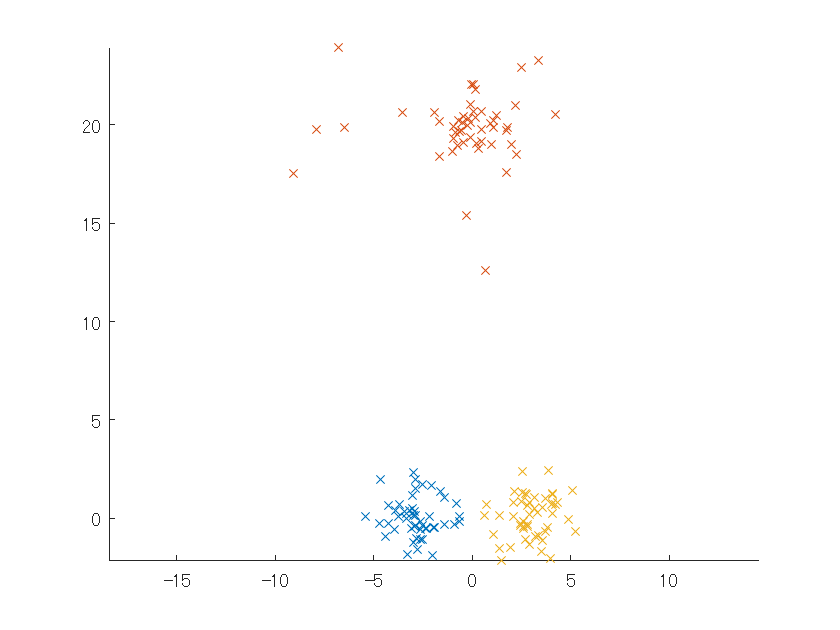

clear;

rng(4);

m = 50;
mt = 10;

X1 = [-3;0] + 1*randn(2,m);
X3 = [+3;0] + 1*randn(2,m);

nu = 2;
chi = gamma_dist(m,nu/2,1/2)';
Y = randn(2,m);
X2 = [0;20] + sqrt(nu./chi).*Y;

X = [X1,X2,X3];
lX = [ones(1,m),2*ones(1,m),3*ones(1,m)];

figure; hold on;
for i=1:3
    plot(X(1,lX==i),X(2,lX==i),'x');
end
axis equal

MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 2.220690e-02 0.000849
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 1.344476e-04 0.000895
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 2.059244e-02 0.000716
post obj = 3.113015e-04
   7.1610e-04

mgn  1.330691e+00	6.954665e-01	1.442221e+00
s    2.003677e+00	1.999791e+00	2.120574e+00
ss    1.000000e+00	1.000000e+00	1.000000e+00
r    5.647359e-05	2.067510e-04	4.807687e-05


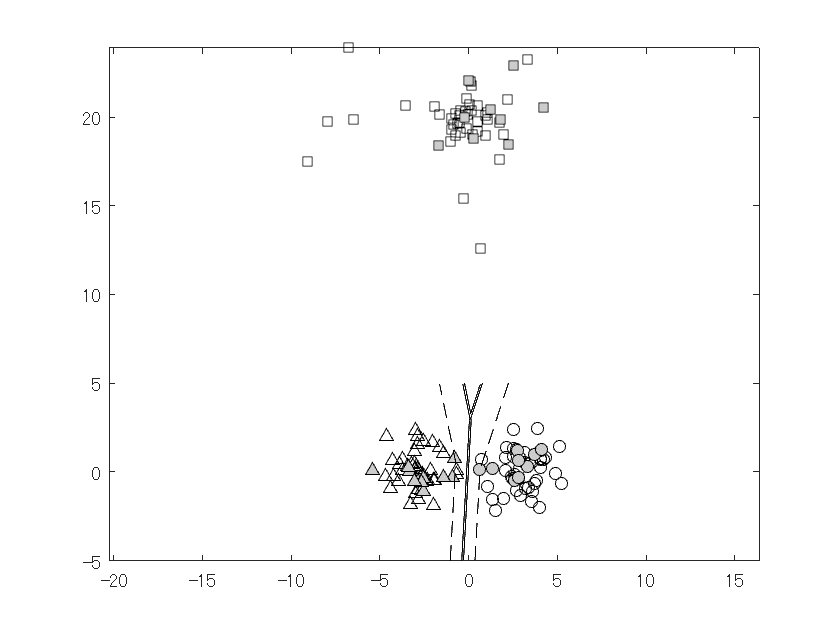

lambda = 1e-2;

t1 = zeros(1,m);
t1(randperm(m,mt)) = 1;
t2 = zeros(1,m);
t2(randperm(m,mt)) = 1;
t3 = zeros(1,m);
t3(randperm(m,mt)) = 1;

t = [t1,t2,t3];

orsvm = @(X,lX) OVRSVM(X,lX,lambda);
plot_boundary(X,lX,t,orsvm);

start mosek
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 2.805379e-02 0.001408
post obj = 1.635060e-02, err = 4.675577e-06, 1.378042e-04, margin = 1.557889e+00, 7.438611e-01, s = 1.000000e+00, 1.000000e+00, post_s = 1.000000e+00, 1.149026e+00
    0.0014

mgn  1.484375e+00	7.438611e-01	1.557889e+00
s    1.000000e+00	1.000000e+00	1.149026e+00
ss    1.000000e+00	1.000000e+00	1.000000e+00
r    4.538508e-05	1.807543e-04	4.120284e-05


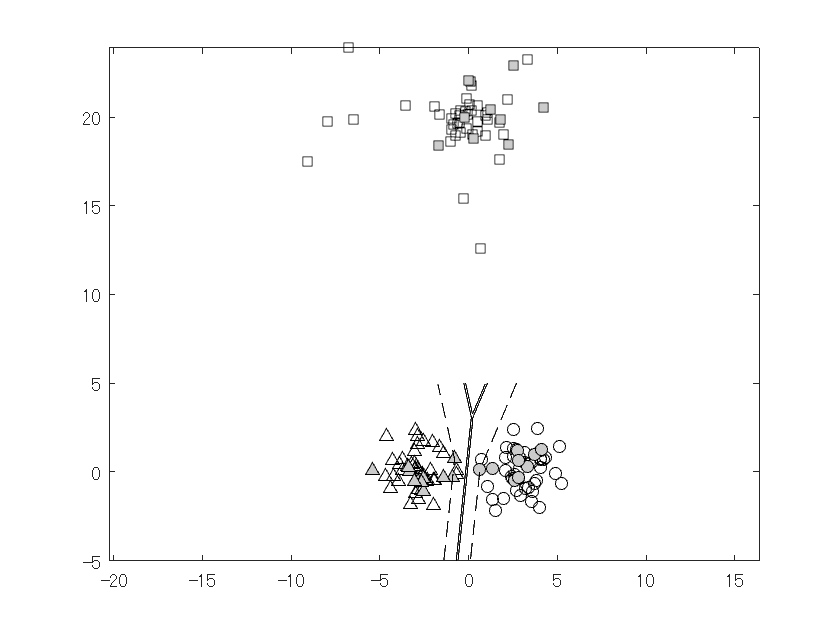


param.lambda = lambda;
param.alpha = 2;
param.is_s_fixed = true;
atsvm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,atsvm);

start mosek
MSK_RES_TRM_STALL OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 1.652463e-01 0.004967
post obj = 1.707531e-02, err = 5.164082e-06, 1.512305e-04, margin = 3.829830e+00, 7.438693e-01, s = 1.000000e+00, 2.760147e+00, post_s = 1.000000e+00, 2.760147e+00
    0.0050

mgn  3.829830e+00	7.438693e-01	2.938387e+00
s    2.180959e+00	1.000000e+00	2.760147e+00
ss    2.180959e+00	1.000000e+00	2.760147e+00
r    7.946661e-04	5.678800e-03	1.092117e-03


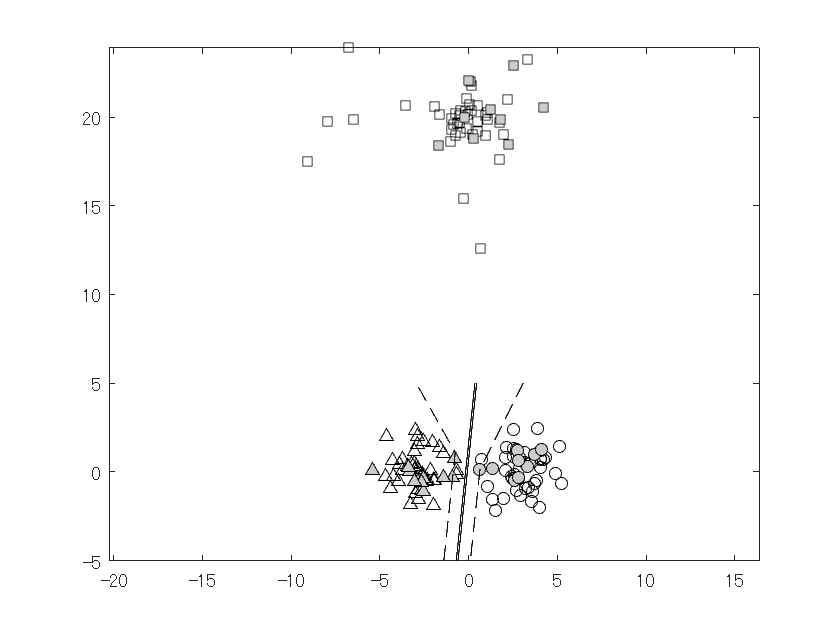


param.alpha = 1.2;
param.is_s_fixed = false;
rgmnsvm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,rgmnsvm);

start mosek
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 2.139787e-02 0.002161
post obj = 1.364320e-02, err = 3.334299e-06, 9.806095e-05, margin = 6.344560e+00, 7.438385e-01, s = 1.000000e+00, 6.851149e+00, post_s = 1.000000e+00, 6.851149e+00
    0.0022

mgn  6.344560e+00	7.438385e-01	5.869745e+00
s    5.371260e+00	1.000000e+00	6.851149e+00
ss    5.371260e+00	1.000000e+00	6.851149e+00
r    2.484261e-06	1.807501e-04	2.902431e-06


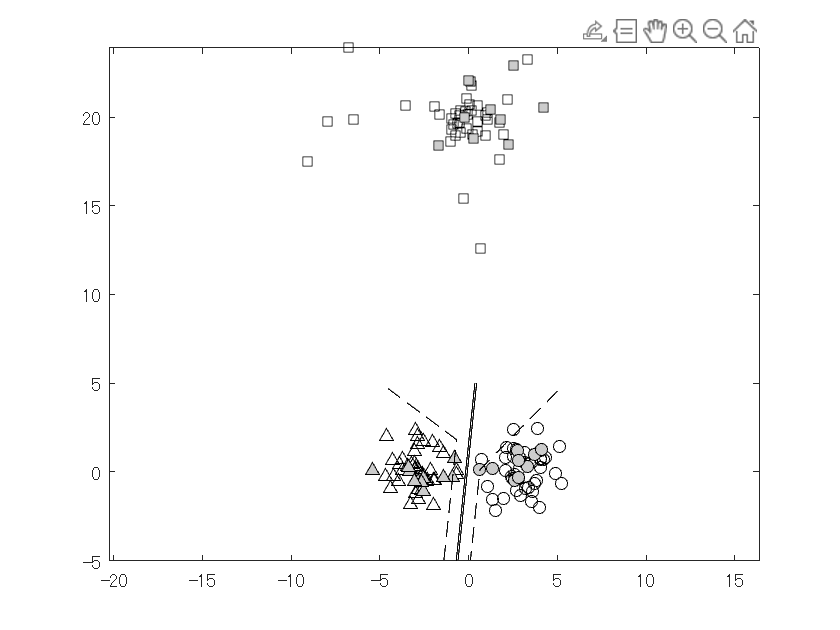


param.alpha = 2;
param.is_s_fixed = false;
rgmnsvm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,rgmnsvm);

start mosek
MSK_RES_OK OPTIMAL PRIMAL_AND_DUAL_FEASIBLE 3.273887e-04 0.001577
post obj = 1.344503e-02, err = 3.071606e-06, 9.042012e-05, margin = 7.647130e+00, 7.438337e-01, s = 1.000000e+00, 1.055308e+01, post_s = 1.000000e+00, 1.055311e+01
    0.0016

mgn  7.647130e+00	7.438337e-01	7.090451e+00
s    9.097758e+00	1.000000e+00	1.055311e+01
ss    9.097746e+00	1.000000e+00	1.055308e+01
r    2.924201e-12	3.267051e-08	3.956448e-12


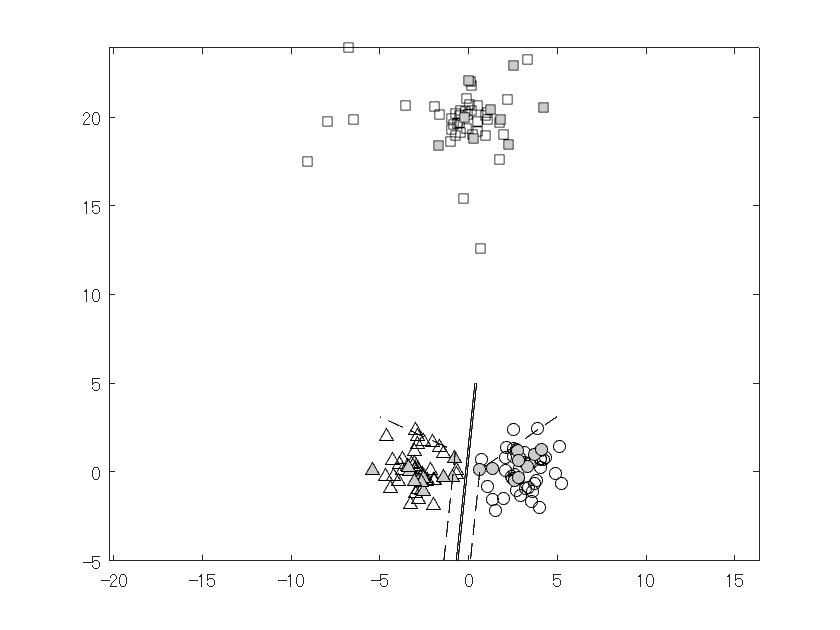


param.alpha = 4;
param.is_s_fixed = false;
rgmnsvm = @(X,lX) RGMNSVM(X,lX,param);
plot_boundary(X,lX,t,rgmnsvm);

function plot_boundary(X,lX,t,svm)

[W,b,res] = svm(X(:,t==1),lX(t==1));

disp(res.msk_time);

mgn = res.margin;
s = res.post_s;
ss = res.s;
r = res.post_r;

disp(['mgn  ',num2str(mgn,'%e\t')]);
disp(['s    ',num2str(s,'%e\t')]);
disp(['ss    ',num2str(ss,'%e\t')]);
disp(['r    ',num2str(r,'%e\t')]);

figure;
hold on;
box on;

scatter(X(1,lX==1&t==0),X(2,lX==1&t==0),'k^');
scatter(X(1,lX==2&t==0),X(2,lX==2&t==0),'ks');
scatter(X(1,lX==3&t==0),X(2,lX==3&t==0),'ko');

scatter(X(1,lX==1&t==1),X(2,lX==1&t==1),'k^','MarkerFaceColor',[.8,.8,.8]);
scatter(X(1,lX==2&t==1),X(2,lX==2&t==1),'ks','MarkerFaceColor',[.8,.8,.8]);
scatter(X(1,lX==3&t==1),X(2,lX==3&t==1),'ko','MarkerFaceColor',[.8,.8,.8]);

f = @(x,y) margin(x,y,W,b);
fcontour(f,'k-','LevelList',[5e-2],'MeshDensity',800);

f = @(x,y) score(x,y,W,b,s);
fcontour(f,'k--','LevelList',[1],'MeshDensity',400);

axis equal;

end

function f = score(x,y,W,b,s)
c = size(W,2);
S = zeros(c);
S(tril(ones(c),-1)==1) = s;
S = S + S' + eye(c);
f = zeros(size(x));
for i=1:numel(x)
    F = W(1,:)*x(i) + W(2,:)*y(i) + b;
    [~,I] = sort(F,'descend');
    FF = -(F(I) - F(I(1)))./S(I,I(1))';
    FF2 = mink(FF,2);
    f(i) = FF2(end);
end
end

function f = margin(x,y,W,b)
f = zeros(size(x));
for i=1:numel(x)
    F = W(1,:)*x(i) + W(2,:)*y(i) + b;
    [~,I] = sort(F,'descend');
    f(i) = (F(I(1)) - F(I(2)))/(norm(W(:,I(1))-W(:,I(2))));
end
end

gamma function

function g = gamma_dist(m,alpha,lambda)
n = ceil(alpha);
delta = alpha - n;

U = rand(n,m);
g = -sum(log(U),1)';

if delta > 1e-9
    for i = 1:m
        while(1)
            u = rand;
            v = rand;
            w = rand;
            if u <= exp(1)/(exp(1)+delta)
                xi = v^(1/delta);
                eta = w*xi^(delta-1);
            else
                xi = 1 - log(v);
                eta = w*exp(-xi);
            end
            if eta <= xi^(delta-1)*exp(-xi)
                break;
            end
        end
        g(i) = g(i) + xi;
    end
end

g = g/lambda;
end